## **EXPERIMENT-1**

## **GENERATION AND OPERATION OF ELEMENTARY SIGNALS **

**23BEC1436**

**Emmanuel Punnoose**

## AIM:

To generate the following Elementary Digital Signals:

1. Discrete Unit Impulse Sequence and Delayed Discrete Unit Impulse Sequence

2. Discrete Unit Step Sequence

3. Discrete Unit Ramp Sequence

4. Discrete Real Exponential Sequences when α < -1, -1 < α < 0, 0 < α < 1, α > 1, α = 1 and α = -1

5. To perform five operations on any Generated Sequences (Operations on Dependent and Independent Variables):

(i) Addition

(ii) Multiplication

(iii) Differentiation with respect to time

(iv) Amplitude Scaling

(v) Amplitude Shifting

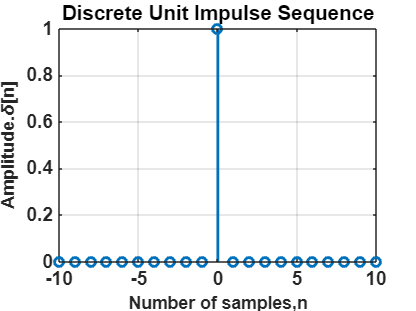

% Discrete Unit Impulse Sequence
close all
n=-10:10;
N3=21;
d= [zeros(1,(N3-1)/2),ones(1,1), zeros(1,(N3-1)/2)];
stem(n,d,'LineWidth',2);
set(gca,'fontsize',13,'fontweight','bold');
xlabel('Number of samples,n','FontSize',12,'FontWeight','bold');
ylabel('Amplitude.\delta[n]','FontSize',12,'FontWeight','bold');
title('Discrete Unit Impulse Sequence','FontSize',14);
grid on;

% Discrete Unit Impulse Sequence with Delay
close all
n=-10:10;
N3=21;
delay=2

delay = 2

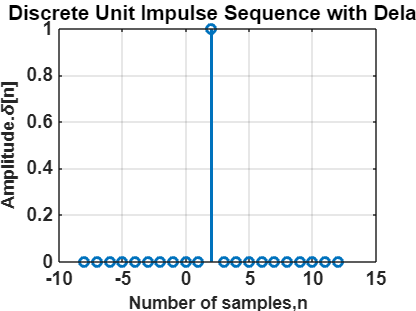

d= [zeros(1,(N3-1)/2),ones(1,1), zeros(1,(N3-1)/2)];
stem(n+delay,d,'LineWidth',2);
set(gca,'fontsize',13,'fontweight','bold');
xlabel('Number of samples,n','FontSize',12,'FontWeight','bold');
ylabel('Amplitude.\delta[n]','FontSize',12,'FontWeight','bold');
title('Discrete Unit Impulse Sequence with Delay','FontSize',14);
grid on;

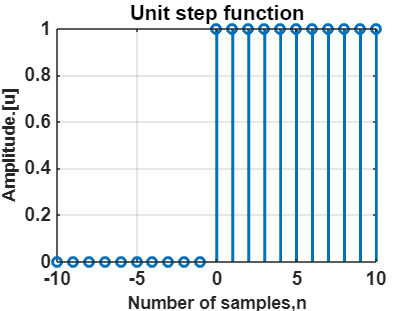

% Unit step function
close all
n=-10:10;
d=(n>=0);
stem(n,d,'LineWidth',2);
set(gca,'fontsize',13,'fontweight','bold');
xlabel('Number of samples,n','FontSize',12,'FontWeight','bold');
ylabel('Amplitude.[u]','FontSize',12,'FontWeight','bold');
title('Unit step function','FontSize',14);
grid on;

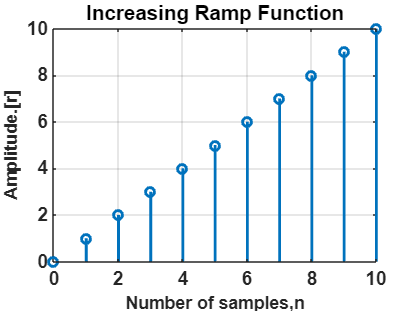

% Increasing Ramp Function
close all
n=0:10;
d=(n>=0).*n;
stem(n,d,'LineWidth',2);
set(gca,'fontsize',13,'fontweight','bold');
xlabel('Number of samples,n','FontSize',12,'FontWeight','bold');
ylabel('Amplitude.[r]','FontSize',12,'FontWeight','bold');
title('Increasing Ramp Function','FontSize',14);
grid on;

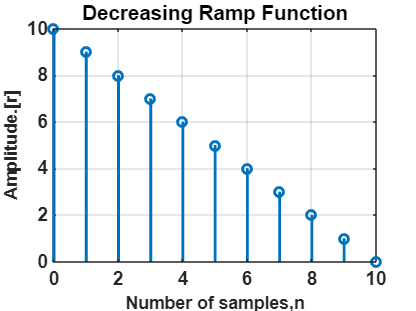

% Decreasing Ramp Function
close all
n=0:10;
d=(n>=0).*(10-n);
stem(n,d,'LineWidth',2);
set(gca,'fontsize',13,'fontweight','bold');
xlabel('Number of samples,n','FontSize',12,'FontWeight','bold');
ylabel('Amplitude.[r]','FontSize',12,'FontWeight','bold');
title('Decreasing Ramp Function','FontSize',14);
grid on;

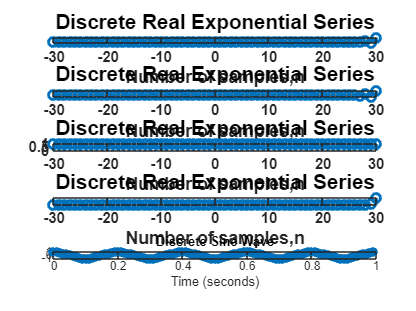

n=-30:30;
d=alpha.^n;
subplot(5,1,1);
alpha=-2.8;
d=alpha.^n;
stem(n,d,'LineWidth',2);
set(gca,'fontsize',10,'fontweight','bold');
xlabel('Number of samples,n','FontSize',12,'FontWeight','bold');
ylabel('Amplitude.exp[n]','FontSize',12,'FontWeight','bold');
title('Discrete Real Exponential Series','FontSize',14);
grid on;
subplot(5,1,2);
alpha=-1.8;
d=alpha.^n;
stem(n,d,'LineWidth',2);
set(gca,'fontsize',10,'fontweight','bold');
xlabel('Number of samples,n','FontSize',12,'FontWeight','bold');
ylabel('Amplitude.exp[n]','FontSize',12,'FontWeight','bold');
title('Discrete Real Exponential Series','FontSize',14);
grid on;
subplot(5,1,3);
alpha=1;
d=alpha.^n;
stem(n,d,'LineWidth',2);
set(gca,'fontsize',10,'fontweight','bold');
xlabel('Number of samples,n','FontSize',12,'FontWeight','bold');
ylabel('Amplitude.exp[n]','FontSize',12,'FontWeight','bold');
title('Discrete Real Exponential Series','FontSize',14);
grid on;
subplot(5,1,4);
alpha=10;
d=alpha.^n;
stem(n,d,'LineWidth',2);
set(gca,'fontsize',10,'fontweight','bold');
xlabel('Number of samples,n','FontSize',12,'FontWeight','bold');
ylabel('Amplitude.exp[n]','FontSize',12,'FontWeight','bold');
title('Discrete Real Exponential Series','FontSize',14);
grid on;
subplot(5,1,5);
alpha=2.8;
d=alpha.^n;
stem(n,d,'LineWidth',2);
set(gca,'fontsize',10,'fontweight','bold');
xlabel('Number of samples,n','FontSize',12,'FontWeight','bold');
ylabel('Amplitude.exp[n]','FontSize',12,'FontWeight','bold');
title('Discrete Real Exponential Series','FontSize',14);
grid on;

% generaion of sinusoidal wave(sine)
f = 5;             
Fs = 100;          
T = 1/Fs;           
L = 100;           
t = (0:L-1)*T;     
y = sin(2*pi*f*t);
stem(t, y, 'filled');
title('Discrete Sine Wave');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;

% generaion of sinusoidal wave(cosine)
f = 5;              
Fs = 100;           
T = 1/Fs;           
L = 100;            
t = (0:L-1)*T;    
y = cos(2*pi*f*t);
stem(t, y, 'filled');
title('Discrete Sine Wave');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;

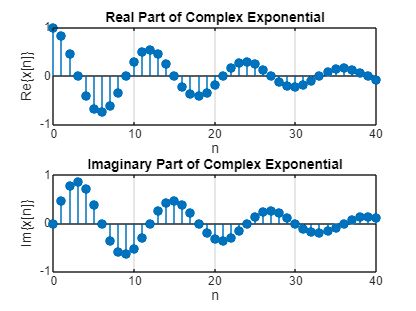


% generation of exponentional signal(real and imaginary)
n = 0:40;
A = 1;
alpha = -0.05;
omega = pi/6;
x = A * exp((alpha + 1j*omega) * n);
figure;
subplot(2,1,1);
stem(n, real(x), 'filled');
title('Real Part of Complex Exponential');
xlabel('n'); ylabel('Re\{x[n]\}');
grid on;

subplot(2,1,2);
stem(n, imag(x), 'filled');
title('Imaginary Part of Complex Exponential');
xlabel('n'); ylabel('Im\{x[n]\}');
grid on;